%r0748760 8 7 7 6 4
Tnew = (8*T1 + 7 *T2 + 7*T3 + 6*T4 + 4*T5)/(8+7+7+6+4);


X1training = X1(1:1000);
X1trainingvalidation = X1(1:2000);
X1validation = X1(1001:2000);
X1test = X1(2001:3000);

X2training = X2(1:1000);

X2trainingvalidation = X2(1:2000);
X2validation = X2(1001:2000);
X2test = X2(2001:3000);

T3trainingvalidation = Tnew(1:2000);
T3validation = Tnew(1001:2000);
T3test = Tnew(2001:3000);

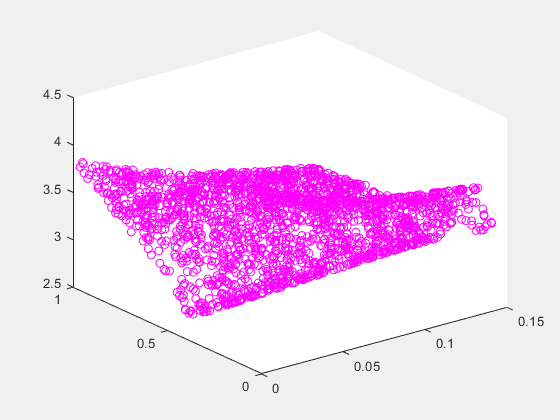

%Scatteredinterpolant creation and figure
%linspace creates a vector of values, take three arguments: 'start', 'stop' and 'n'. Start and stop are selfexplanatory, n is the number of evenly spaced values that are generated between start and stop.
X = linspace(min(X1trainingvalidation),max(X2trainingvalidation),25); 
Y = linspace(min(X2trainingvalidation),max(X2trainingvalidation),25); 
%meshgrid creates a gird of coordinates for given range x and y.
[xq, yq] = meshgrid(X,Y); 
%scatteredInterpolant takes a set of scattered data points and constructs a surface that passes throught these points. This surface can then be used to interpolate values at new points within the range of original data
F1 = scatteredInterpolant(X1trainingvalidation,X2trainingvalidation,T3trainingvalidation);

zq = griddata(X1trainingvalidation,X2trainingvalidation,T3trainingvalidation,xq,yq); 
plot3(X1trainingvalidation,X2trainingvalidation,T3trainingvalidation,'mo')
hold on

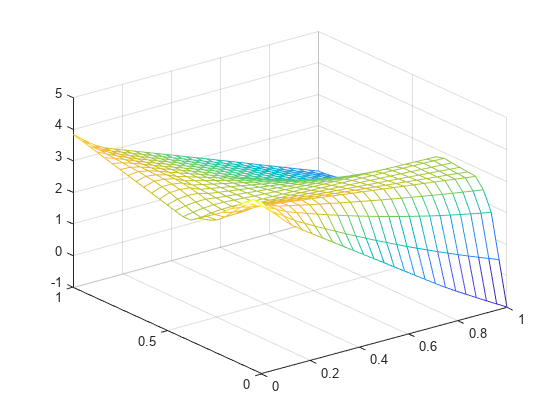

figure
vq1 = F1(xq,yq);
mesh(xq,yq,vq1)
hold off

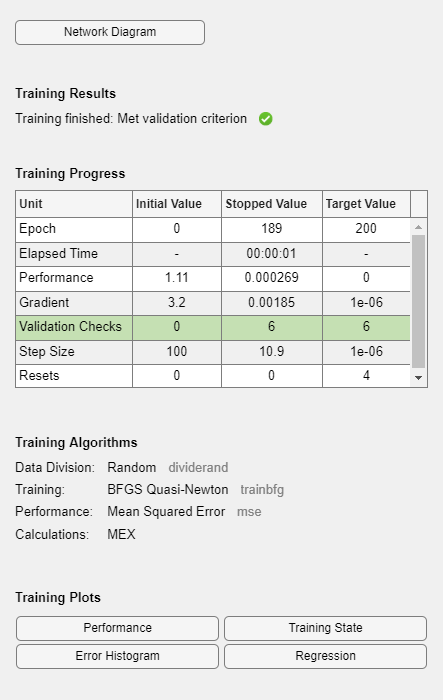

%Neural network creation net1
x1 = X1trainingvalidation;
x2 = X2trainingvalidation;
t1 = T3trainingvalidation;
Xcomb = horzcat(X1trainingvalidation, X2trainingvalidation);

net1 = feedforwardnet(10,'trainbfg');

net1=configure(net1,Xcomb',t1');


net1=init(net1);% Initialize the weights (randomly)

%net1.layers{1}.transferFcn = 'purelin';
%net1.layers{2}.transferFcn = 'purelin';
net.divideMode = 'sample';
net.divideParam.trainRatio = 0.5 ;
net.divideParam.valRatio = 0.5;
net.divideParam.testRatio = 0.0;
net1.trainParam.epochs=200;
net1 = train(net1, Xcomb',t1');



XtestComb = horzcat(X1test,X2test);

outputs1 = net1(XtestComb');
performance1 = perform(net1,T3test,outputs1)

performance1 = 0.1113

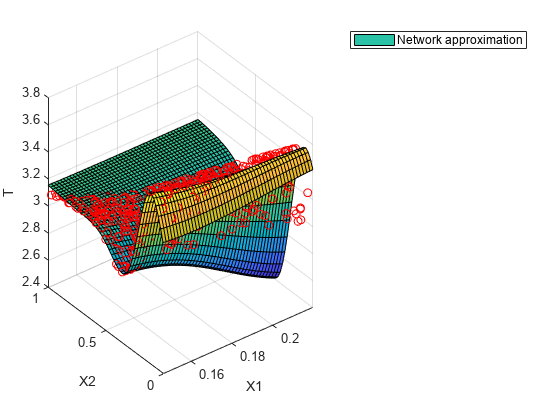

[Xtest1, Xtest2] = meshgrid(linspace(min(XtestComb(:,1)), max(XtestComb(:,1)), 50), linspace(min(XtestComb(:,2)), max(XtestComb(:,2)), 50));
Ytest_net = sim(net1, [Xtest1(:)'; Xtest2(:)']);
Ytest_net = reshape(Ytest_net, size(Xtest1));
figure;
surf(Xtest1, Xtest2, Ytest_net);
hold on;
scatter3(XtestComb(:,1), XtestComb(:,2), T3test(:),  'r');
xlabel('X1');
ylabel('X2');
zlabel('T');
legend('Network approximation');

XtestComb = horzcat(X1test,X2test);
outputs1 = net1(XtestComb');
performance1 = perform(net1,T3test,outputs1)

performance1 = 0.1113

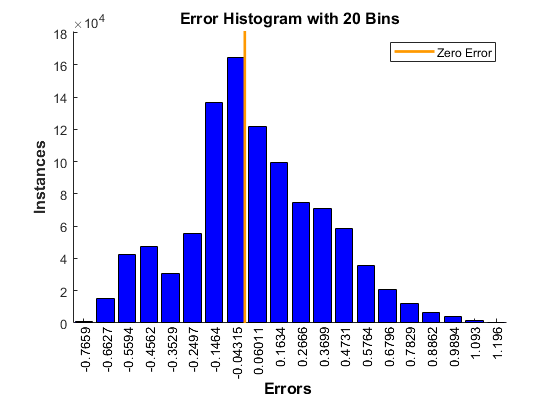

e= T3test-outputs1;
figure;
ploterrhist(e);

ploterrsurf()